**Exercise 1**

Double pendulum has the following coupled 2nd order ODEs


$$\left(m_1 +m_2 \right)l_1 \ddot{\theta_1 } +m_2 l_2 \ddot{\theta_2 } \cos \left(\theta_1 -\theta_2 \right)=-m_2 l_2 \dot{\theta_2^2 } \sin \left(\theta_1 -\theta_2 \right)-g\left(m_1 +m_2 \right)\sin \theta_1$$



$$m_2 l_2^2 \ddot{\theta_2 } +m_2 l_1 l_2 \ddot{\theta_1 } \cos \left(\theta_1 -\theta_2 \right)=m_2 l_1 l_2 \dot{\theta_1^2 } \sin \left(\theta_1 -\theta_2 \right)-l_2 m_2 g\;\sin \;\theta_2$$


Consider the following condition

$m_1 =1$,    $m_2 = 4$,    $l_1 = 2$,    $l_2 = 3$


$$\theta_{1,0} = \theta_{2,0} = \frac{\pi}{2}$$



$$\dot{\theta}_{1,0} = \dot{\theta}_{2,0} = 0$$


- Solve it using your RK4 solver for $t  = 0 \ldots 10s$

- Plot the two angles as graphs

- Animate the results to verify

- Try different ICs to verify.

Hint: Set it up as a matrix equation first: $[A]\ddot{\theta} = \{ R\}$ to find accelerations.

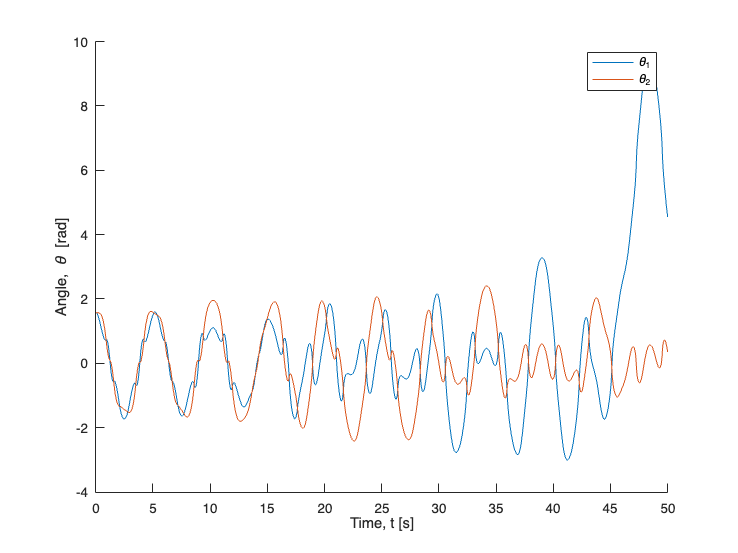

% Double Pendulum 
% EOMs from https://scienceworld.wolfram.com/physics/DoublePendulum.html
clc; clear variables; close all;

%  Initial conditions
theta0  = [pi/2; pi/2];  % rad
thetaD0 = [0; 0];        % rad/s

%Vector of all four initial conditions Y0 = [theta1; theta1D; theta2; theta2D]
Y0 = [theta0(1); thetaD0(1); theta0(2); thetaD0(2)];

% time
h  = 0.01;
t  = 0:h:50;
nt = length(t);

% solve
Y = odesRK4(@ode_double_pendulum,Y0,t);
theta1 = Y(1,:);
theta2 = Y(3,:);

% plot results
figure
axes
hold on
plot(t,theta1);
plot(t,theta2);
xlabel('Time, t [s]');
ylabel('Angle, \theta [rad]')
legend('\theta_1','\theta_2')

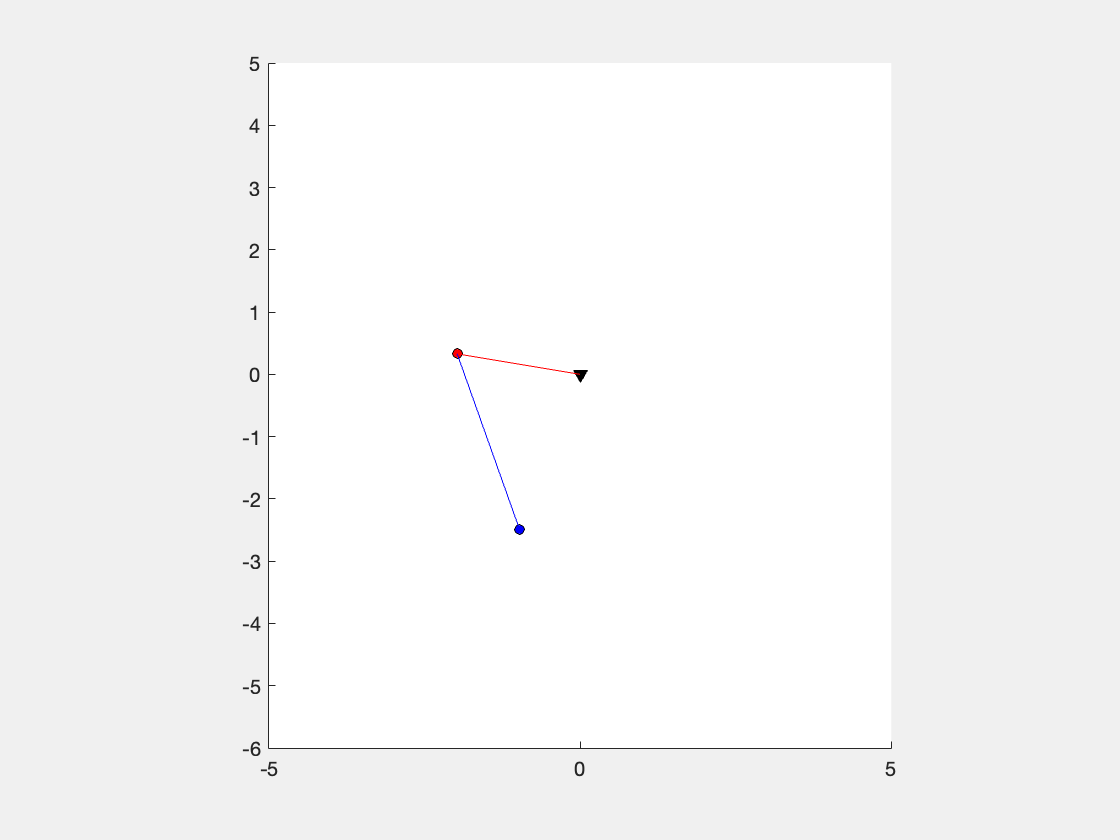


% animate
l  = [2 3];   % pendulum lengths
figure
axes
hold on
axis equal
xlim([-5 5]) 
ylim([-6 5]) 
plot(0,0,'vk','markerfacecolor','k')
hmass(1) = plot(0,0,'ok','markersize',5,'markerfacecolor','r');
hmass(2) = plot(0,0,'ok','markersize',5,'markerfacecolor','b');
hlink(1) = plot([0 0],[0 0],'r-');
hlink(2) = plot([0 0],[0 0],'b-');

tic
for i = 1:nt

    % calc. updated (x,y) locations of both masses
    x = [l(1)*sin(theta1(i));
         l(1)*sin(theta1(i)) + l(2)*sin(theta2(i))];
    y = [-l(1)*cos(theta1(i));
         -l(1)*cos(theta1(i)) - l(2)*cos(theta2(i))];

    % update plot
    hmass(1).XData = x(1);
    hmass(1).YData = y(1);
    hmass(2).XData = x(2);
    hmass(2).YData = y(2);

    hlink(1).XData(2) = x(1);
    hlink(1).YData(2) = y(1);
    hlink(2).XData = x;
    hlink(2).YData = y;

    pause(0.0047)
    if i==1
        waitforbuttonpress;
    end
end

toc

Elapsed time is 30.611988 seconds.





function f = ode_double_pendulum(Y_ins)
% Returns derivatives of Y at t
% Y = [theta1; thetaD1; theta2; thetaD2]
% f = [f1; f2; f3; f4]

    % rename back
    Y1 = Y_ins(1);       % theta1
    Y2 = Y_ins(2);       % thetaD1
    Y3 = Y_ins(3);       % theta2
    Y4 = Y_ins(4);       % thetaD2
    
    g  = 9.8;            % acc. due to gravity (positive)
    l  = [2 3];          % pendulum lengths
    m  = [1 4];          % pendulum masses
    
    % setup {R} vector and [A] matrix 
    R = zeros(4 , 1);
    R(1 , 1) = Y2;
    R(2 , 1) = -m(2)*l(2)*Y4^2*sin(Y1-Y3)-g*(m(1)+m(2))*sin(Y1);
    R(3 , 1) = Y4;
    R(4 , 1) = m(2)*l(1)*l(2)*Y2^2*sin(Y1-Y3)-g*m(2)*l(2)*sin(Y3);

    A = zeros(4 , 4);
    A(1 , 1) = 1;
    A(2 , 2) = (m(1) + m(2))*l(1);
    A(2 , 4) = m(2)*l(2)*cos(Y1-Y3);
    A(3 , 3) = 1;
    A(4 , 2) = m(2)*l(1)*l(2)*cos(Y1-Y3);
    A(4 , 4) = m(2)*l(2)^2;

    % calculating the vector of ODE functions at moment t
    f = A\R;    
end

**Exercise 2**

For the following system of equations find the maximum time step that can be selected to avoid instability while using Forward Euler Method.


$$\left\lbrace \begin{array}{ll}
\;\dot{y_1 } =-56y_1 +55y_2  & \;\\
\dot{y_2 } =44y_1 -45y_2  & \;
\end{array}\right.$$


For $0 \leq t \leq 10$ and $y_1(0) = 2.8, y_2(0) = 1$.

Then in your Forward Euler code test if the calculated $h$ for stability assurance is correct. 

clear variables; close all; clc;

% System matrix
A = [-56, 55;
     44, -45];

% Eigenvalues
lambda = eig(A);

% Maximum timestep for Forward Euler stability
h_max = min(-2 ./ real(lambda));   % works here since both eigenvalues are negative real

fprintf('Eigenvalues:\n');

Eigenvalues:


disp(lambda)

  -100
    -1




fprintf('Maximum stable timestep (theoretical): h_max = %.5f\n', h_max);

Maximum stable timestep (theoretical): h_max = 0.02000


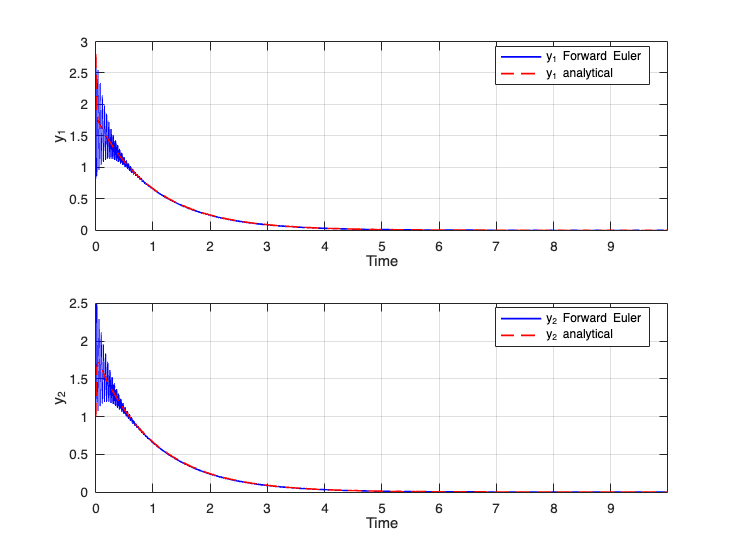


% Choose a slightly smaller timestep for safety
h = h_max - 0.001;

% Time settings
t = 0:h:10;

% Initial conditions (column vector)
Y0 = [2.8; 1];

% Solve system with Forward Euler
Y = odeFE(@odefun, Y0, t);

% Analytical solution
y1_analytic = 1.8*exp(-t) + exp(-100*t);
y2_analytic = 1.8*exp(-t) - 0.8*exp(-100*t);

% Plotting
figure
subplot(2,1,1)
plot(t, Y(1,:), 'b', t, y1_analytic, 'r--', 'LineWidth', 1.2)
xlabel('Time')
ylabel('y_1')
legend('y_1 Forward Euler','y_1 analytical','Location','best')
grid on
xlim([0 t(end)])

subplot(2,1,2)
plot(t, Y(2,:), 'b', t, y2_analytic, 'r--', 'LineWidth', 1.2)
xlabel('Time')
ylabel('y_2')
legend('y_2 Forward Euler','y_2 analytical','Location','best')
grid on
xlim([0 t(end)])

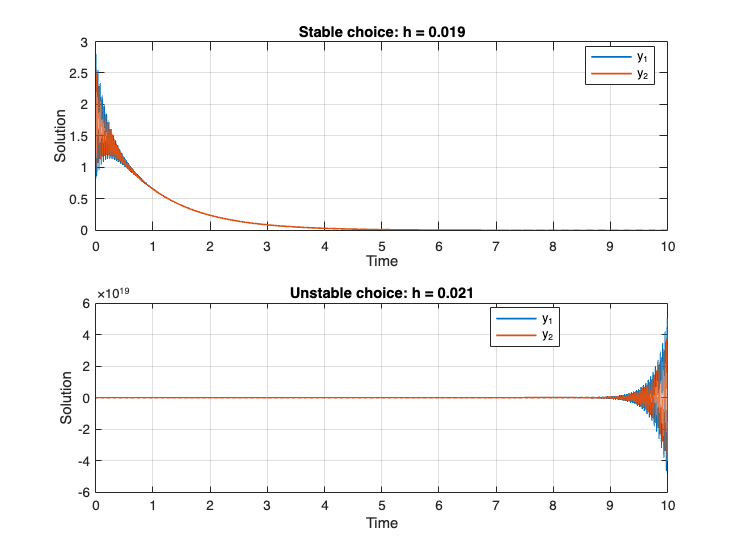


% Test near instability
h_test1 = 0.019;   % stable
h_test2 = 0.021;   % unstable

t1 = 0:h_test1:10;
t2 = 0:h_test2:10;

Y1 = odeFE(@odefun, Y0, t1);
Y2 = odeFE(@odefun, Y0, t2);

figure
subplot(2,1,1)
plot(t1, Y1(1,:), t1, Y1(2,:), 'LineWidth', 1.2)
title('Stable choice: h = 0.019')
xlabel('Time')
ylabel('Solution')
legend('y_1','y_2','Location','best')
grid on

subplot(2,1,2)
plot(t2, Y2(1,:), t2, Y2(2,:), 'LineWidth', 1.2)
title('Unstable choice: h = 0.021')
xlabel('Time')
ylabel('Solution')
legend('y_1','y_2','Location','best')
grid on



function dYdt = odefun(Y, ~)
    A = [-56, 55;
         44, -45];
    dYdt = A*Y;
end

function Y = odeFE(ODEfun, Y0, t)
    n = length(t);          % number of time steps
    m = length(Y0);         % number of equations

    Y = zeros(m, n);
    Y(:,1) = Y0;

    for k = 1:n-1
        h = t(k+1) - t(k);
        Y(:,k+1) = Y(:,k) + h*ODEfun(Y(:,k), t(k));
    end
end

**Exercise 3**

A non-conservative, oscillating system with non-linear damping has the following governing equation. Try to solve this second order differential equation using two Matlab solvers: `ode45` and `ode23s`


$$\ddot{x} -\mu \;\left(1-x^2 \right)\dot{x} +x=0$$


Initial conditions: $x_0 = 2$ and $\dot{x}_0 = 0$. $\mu = 1000$.

Plot the results of the two methods in separate figures.

Compare the computing time of the two methods using `tic and toc before and after corresponding lines for each method in your code.`

`Compare the number of time steps generated in the two methods.`

% Simple pendulum ODE
clc; clear variables; close all;

x0  = 2;          % Initial value of Theta in rad
xD0 = 0;          % Initial value of first derivative of Theta in rad/s

Y0 = [x0  xD0];

% solve
tic
[t1 , Y] = ode45(@ODEfun,[0 3000],Y0);
x_ode45 = Y(:,1);      % column vector of x in time

subplot(2,1,1) 
plot(t1, x_ode45, 'r' )
legend(' Numerical solution ode45')
xlabel('Time');
ylabel('x')
ylim([-2.5 3])
toc

Elapsed time is 8.379778 seconds.


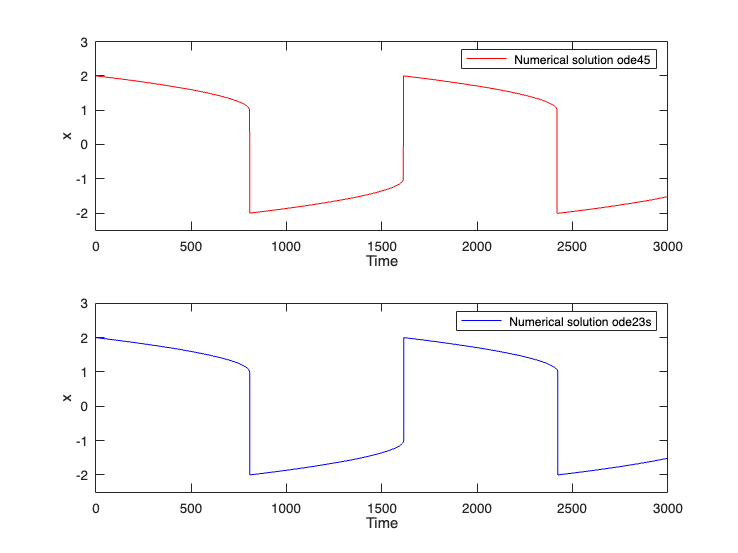


tic
[t2 , Y] = ode23s(@ODEfun,[0 3000],Y0);
x_ode23s = Y(:,1);      % column vector of x in time

subplot(2,1,2) 
plot(t2, x_ode23s, 'b' )
legend(' Numerical solution ode23s')
xlabel('Time');
ylabel('x')
ylim([-2.5 3])

toc

Elapsed time is 0.169282 seconds.





function f = ODEfun(t , Y_ins)
% Returns derivatives of Y at t
% Y_ins = [x xD]                The 2*1 input vector at each moment
% f = [f1; f2]                  The vector ODE functions at Y and t

    % rename back
    Xi  = Y_ins(1);             % instant value of x
    XDi = Y_ins(2);             % instant value of xD

    mU = 1000;                  % Damping coefficient

    f1 = XDi;                   % value of first ODE function
    f2 = mU*(1-Xi^2)*XDi-Xi;    % value of second ODE function
    f  = [f1 ; f2];             % Vector of ODE function calculated based on the inputs 
    
end